# Embedded solver solution for Regional pole placement

clear all ; close all ;

## Motor Parameters and model

 
model.R = 0.656;         % Ohm
model.L = 0.35e-3;       % H
model.Phif = 6.6e-3;     % Wb
model.p = 4;
model.F = 1.e-05;
model.J = 1e-05;
disp(model);

       R: 0.6560
       L: 3.5000e-04
    Phif: 0.0066
       p: 4
       F: 1.0000e-05
       J: 1.0000e-05




% State space representation of the motor model

A = [-model.R/model.L -model.p*model.Phif ; 3*model.p*model.Phif/(2*model.J) -model.F/model.J ];
B = [1/model.L;0];
C = [0 1];
n=size(A,1); 
% Augmented model with integral action
A = [A zeros(n,1);-C 0] ; 
B=[B;0]; 


## Optimization problem

 
alpha =170;
beta =1.6 ;

K = LMI_embSolver(A,B,alpha,beta);


eig_A_BK = eig(A+B*K);
disp(['K=[' num2str(K) ']'])

K=[0.30138   -0.053731      7.9696]


disp(['eig_A_BK=[' num2str(eig_A_BK') ']'])

eig_A_BK=[-405.6588-529.0423i          -405.6588+529.0423i                 -202.8837+0i]


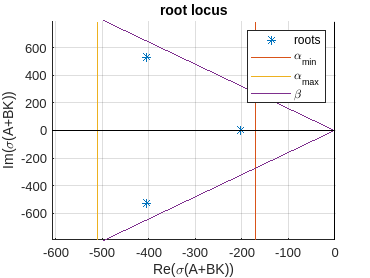


figure;clf;
xmin = 1.5*min(real(eig_A_BK)); xmax = 1; ymin = 1.5*min(imag(eig_A_BK)); ymax = 1.5*max(imag(eig_A_BK));
hold on
grid on
plot(real(eig_A_BK),imag(eig_A_BK),'*')
plot([-alpha -alpha],[ymin ymax])
plot([-3*alpha -3*alpha],[ymin ymax])
plot([-3*alpha 0],[3*alpha*beta 0],'color','#7E2F8E')
plot([-3*alpha 0],[-3*alpha*beta 0],'color','#7E2F8E')
plot([0 0],[ymin ymax],'k')
plot([xmin xmax],[0 0],'k')
axis([xmin xmax ymin-1 ymax+1])
title('root locus')
xlabel('Re(\sigma(A+BK))')
ylabel('Im(\sigma(A+BK))')
legend('roots','\alpha_{min}','\alpha_{max}','\beta')

function [K] = LMI_embSolver(A,B,alpha,beta)
alphamax = 3* alpha ;
tol = 1e-3;
n=size(A,1); m=size(B,2);
warning('off');
tol=1e-3; % tolerance (1e-3 usually is OK)
%%% end inputs

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% LIST OF UKNOWNS (lambda is the first, always included)
Nunk=2;
UNK=cell(Nunk,1);

UNK{1}.lab='X';
UNK{1}.col=n;
UNK{1}.row=n;
UNK{1}.sym=1; % symmetric

UNK{2}.lab='Y';
UNK{2}.row=m;
UNK{2}.col=n;
UNK{2}.sym=0; % generic

Ncon=4;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%

nunk=1 ; %lambda
for j=1:Nunk
    UNK{j}.start=nunk+1;
    if UNK{j}.sym
       
        if UNK{j}.row~=UNK{j}.col
            error('Symmetric matrix not consistent');
        end

        i=0;

        UNK{j}.siz=UNK{j}.row*(UNK{j}.row+1)/2;
        UNK{j}.X=cell(UNK{j}.siz,1);              
        nunk=nunk+UNK{j}.siz;
        UNK{j}.ste=zeros(UNK{j}.row,UNK{j}.col);
        for ii=1:UNK{j}.row
            for iii=ii:UNK{j}.col
                i=i+1;
                Xt=zeros(UNK{j}.row,UNK{j}.col);
                Xt(ii,iii)=1;
                Xt(iii,ii)=1;
                UNK{j}.X{i}=Xt;
            end
        end        
    else

        
        i=0;
        UNK{j}.siz=UNK{j}.row*UNK{j}.col;
        nunk=nunk+UNK{j}.siz;        
        UNK{j}.X=cell(UNK{j}.siz,1);     
        UNK{j}.ste=zeros(UNK{j}.row,UNK{j}.col);
        
        for ii=1:UNK{j}.row
            for iii=1:UNK{j}.col
                i=i+1;
                Xt=zeros(UNK{j}.row,UNK{j}.col);
                Xt(ii,iii)=1;
                UNK{j}.X{i}=Xt;
            end
        end

    end
    UNK{j}.end=nunk;
    
end


F=cell(Ncon,nunk+1);
Ft=cell(Ncon,2);
FF=cell(Ncon,1);
FFINV=cell(Ncon,1);
V=cell(Ncon,nunk);
maxeig=zeros(Ncon,1);

for i=1:nunk+1

   
    %%% done later
    
        for j=1:Nunk
            UNK{j}.ste=0*UNK{j}.ste;
        end
        % find in which unknown it is
        for j=1:Nunk
            if i >= UNK{j}.start && i <= UNK{j}.end
                break
            end
        end
        if j>Nunk && i~=nunk+1
            error('');
        end

        for l=1:2
        
            if l==2 && i~=nunk+1 && i~=1
                UNK{j}.ste=UNK{j}.X{i-UNK{j}.start+1};
            end
            
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            %%% edit here %%%
    
            X=UNK{1}.ste;
            Y=UNK{2}.ste;
            
            Ft{1,l}=X;
            Ft{2,l}=-B*Y-Y'*B'-2*alpha*X-X*A'-A*X;
            Ft{3,l}=-[beta*(X*A'+A*X)  A*X-X*A'; (A*X-X*A')'  beta*(X*A'+A*X)]-...
                    [beta*(Y'*B'+B*Y)  B*Y-Y'*B'; ( B*Y-Y'*B')'  beta*(Y'*B'+B*Y)]; 
            Ft{4,l}=B*Y+Y'*B'+2*alphamax*X+X*A'+A*X;
            %%% end edit %%%    
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        end
        for c=1:Ncon
            
           if i==nunk+1 %%% F0 constant term
               F{c,i}=Ft{c,1}; 
               maxeig(c)=min(real(eig(F{c,i})));
           elseif i==1
           
               F{c,i}=eye(size(Ft{c,2},2));  %%% lambda term
           else
               F{c,i}=Ft{c,2}-Ft{c,1};       %%% standard terms    
           end
        end
        
    %%%

    
end

%

%V1=zeros(nF,nF,nunk);
%grad=zeros(nunk,1);
%hess=zeros(nunk,nunk);

%V1=zeros(nF*nF,nunk);
grad=zeros(nunk,1);
hess=zeros(nunk,nunk);



theta=0;%.1;
x0=[-min([min(maxeig) 0])+1; zeros(nunk-1,1)];


it=0;
x=x0;
t=1;
%%
while 1
   it=it+1;
   x00=x;
   j=0;
   while 1
       j=j+1;
       grad=x*0;
       %FF=(F(:,:,end));
       for c=1:Ncon
            %keyboard
            Ft{c,1}=F{c,end};
            for i=1:nunk
                  Ft{c,1}=Ft{c,1}+x(i)*F{c,i}; 
                  
            end
            %keyboard
            FF{c}=Ft{c,1};
            FFINV{c}=FF{c}^-1; 
            %pause
       end

      
       for i=1:nunk
               
           for c=1:Ncon
                V{c,i}=FFINV{c}*F{c,i};
                grad(i)=grad(i)-trace(V{c,i});
           end
       end
       
       grad(1)=grad(1) + t;
       
       hess=0*hess;
       for i=1:nunk
           for ii=i:nunk
               for c=1:Ncon
                   hess(i,ii)=hess(i,ii)+trace(V{c,i}*V{c,ii});
                   if i~=ii && c==Ncon
                        hess(ii,i)=hess(i,ii);
                   end
               end
           end
       end
       
       %hess(1,1)=hess(1,1);%+ 1/(l0-x(1))^2;
      
       x=x- hess\grad; 


       if norm(x-x00)<=tol || x(1)<=-tol%1
            break;
       end
       x00=x;     
   end 

   
   if norm(x-x0)<=tol || x(1)<=-tol %1
       break;
   end
   %l0=theta*(x0(1))+(1-theta)*l;
   t=1.5*t;
   x0=x;
   
   
end







%disp('number of iterations'); it;

if  x(1)<= -tol %0
    %disp('feasible problem');
    for j=1:Nunk
        UNK{j}.ste=0*UNK{j}.ste;
    end
    
    
    
    for i=2:nunk

        for j=1:Nunk
            if i >= UNK{j}.start && i <= UNK{j}.end
                break
            end
        end
        UNK{j}.ste=UNK{j}.ste+x(i)*UNK{j}.X{i-UNK{j}.start+1};

    end       
    X=UNK{1}.ste;
    Y=UNK{2}.ste;
    P=X^-1; 
    K=Y*P;
     
   
    
else
    disp('infeasible problem');
end
end